#  MATLAB Image Processing Basics - Lab 3: Transportation Application (Pavement Crack Detection)

**Computer Applications in Transportation (2101553)**

**Siwarak Unsiwilai, Ph.D.**

Email: [siwarak.u@chula.ac.th](mailto:siwarak.u@chula.ac.th) Office: CE Building, Room 534

**Learning Objectives:**

- Apply the full 5-step image processing pipeline to a real-world transportation problem: automatically detecting and measuring pavement cracks.

**Instructions**

**1. Download the Lab Files:** Download the `.zip` folder for this lab from our course website.

**2. Extract the Folder:** Unzip the folder and save it somewhere you can easily find, like your Desktop.

**3. Set Your MATLAB Path:**

- Open MATLAB.

- In the "Current Folder" browser, navigate *inside* the folder you just unzipped.

- You should see this `.mlx` file and one or more `.jpg` image files (e.g., `crack_image_1.jpg`).

**4. Ready to Go:** You are now ready to run the lab. All files are in the correct place.

## Initial Step: Check for Required Toolbox

We first check if the Image Processing Toolbox is installed.

%% Initial Step: Check for Required Toolbox
% This lab requires the Image Processing Toolbox. Let's check if it's installed.

% Clear workspace for a fresh start
clear all;
clc;
close all;

% --- Toolbox Check ---
% Use 'ver' to get version info for all toolboxes
toolbox_info = ver;

% Check if 'Image Processing Toolbox' is in the list of names
is_installed = any(strcmp({toolbox_info.Name}, 'Image Processing Toolbox'));

% *** CORRECTED LOGIC ***
if is_installed
    disp('Success: Image Processing Toolbox is installed.');
    disp('You can run the rest of the script.');
else
    % If not installed, stop the script and show an error
    error(['Image Processing Toolbox not found. Please install it to continue.' ...
           '\n\nTo install:' ...
           '\n1. Go to the Home tab' ...
           '\n2. Click Add-Ons > Manage Add-Ons' ...
           '\n3. Search for "Image Processing Toolbox" and install it.' ...
           '\n4. Restart MATLAB and run this script again.']);
end

Success: Image Processing Toolbox is installed.


You can run the rest of the script.


## The Problem

Manually inspecting roads for cracks is slow, expensive, and subjective. We will write a script that follows the 5-step pipeline to automatically find and measure cracks from a photo.

We will base our lab on the **RDD2022 dataset**, a large-scale, multi-national road damage dataset. This is real-world data used by researchers to train AI models for automated road maintenance.

- **Source:** RDD2022 - The multi-national Road Damage Dataset released through CRDDC'2022, [https://figshare.com/articles/dataset/RDD2022_-_The_multi-national_Road_Damage_Dataset_released_through_CRDDC_2022/21431547/1](https://figshare.com/articles/dataset/RDD2022_-_The_multi-national_Road_Damage_Dataset_released_through_CRDDC_2022/21431547/1)

### Step 1: Acquisition

First, we load the image provided in your lab folder.

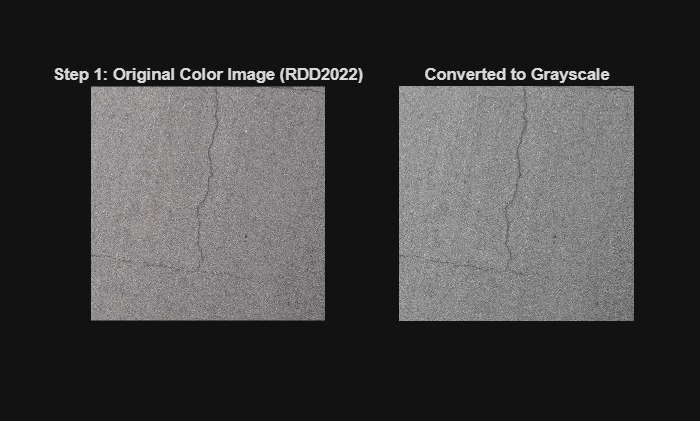

% --- STAGE 1: ACQUISITION ---

% Load the sample image from our lab folder.
% (Make sure you are in the correct "Current Folder")
img_color = imread('crack_1.jpg'); 

% This is a color image. For our analysis, we must
% convert it to a 2D grayscale matrix.
img_gray = rgb2gray(img_color);

figure;
subplot(1, 2, 1);
imshow(img_color);
title('Step 1: Original Color Image (RDD2022)');

subplot(1, 2, 2);
imshow(img_gray);
title('Converted to Grayscale');

### **Step 2: Pre-processing**

The grayscale image has a lot of texture and small shadows that are not cracks. We'll use a filter to smooth the image. A `medfilt2` is good, but we can also use `imgaussfilt` to gently blur the texture.

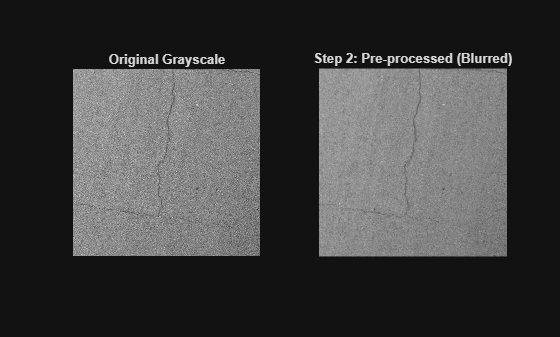

% --- STAGE 2: PRE-PROCESSING ---
% Apply a Gaussian filter to blur the pavement texture
% A small sigma value blurs it just a little.
% img_preprocessed = imgaussfilt(img_gray, 1.0);
 img_preprocessed = medfilt2(img_gray, [3 3]);
figure;
subplot(1, 2, 1);
imshow(img_gray);
title('Original Grayscale');

subplot(1, 2, 2);
imshow(img_preprocessed);
title('Step 2: Pre-processed (Blurred)');

### **Step 3: Segmentation**

Now we create our binary mask. Unlike rice (which was bright), **cracks are dark**. This means we need to find pixels *below* the threshold.

We will use **adaptive thresholding** because the lighting on pavement is almost never even.

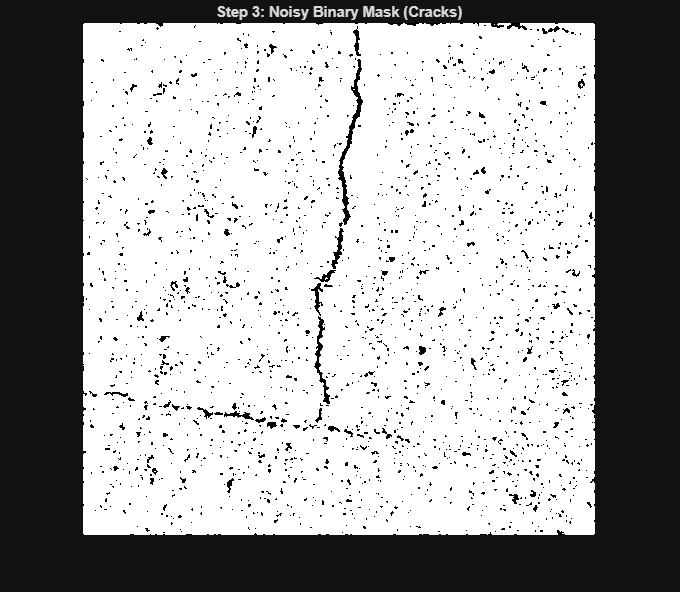

% --- STAGE 3: SEGMENTATION ---
% We use 'adaptive' to handle uneven lighting on the road.
% We set 'ForegroundPolarity' to 'dark' to find dark cracks
% on a light background.
BW_noisy = imbinarize(img_preprocessed, 'adaptive', ...
    'ForegroundPolarity', 'dark', 'Sensitivity', 0.5);

figure;
imshow(BW_noisy);
title('Step 3: Noisy Binary Mask (Cracks)');

### Step 4: Feature Extraction (Cleaning the Mask)

This step is crucial. We need to clean our noisy mask.

- The crack lines are "broken" or "dashed."

- There are a few tiny black "noise" specks.

We will use `imclose` to solve problem 1, and `imopen` to solve problem 2.

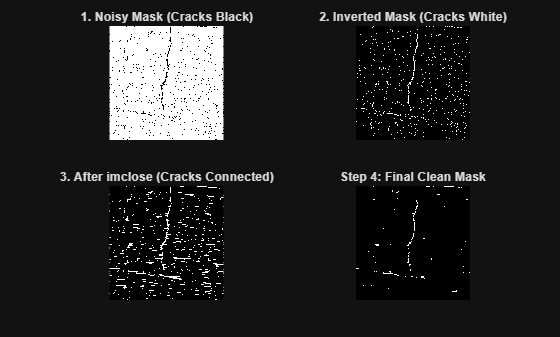

% --- STAGE 4: FEATURE EXTRACTION (CLEANING) ---
% 'BW_noisy' is our excellent mask from Step 3.

% 1. Invert the mask.
% Our functions (imopen, imclose) work on *white* objects.
% Right now, our cracks are black. We must invert the image.
BW_inverted = ~BW_noisy;

% 2. Define "brushes" to clean and connect.
se_connect = strel('line', 15, 0); % Connect horizontal lines
se_noise = strel('disk', 2);     % Remove small (now white) noise specks

% 3. Connect the broken crack lines.
BW_closed = imclose(BW_inverted, se_connect);

% 4. Remove any remaining noise specks.
BW_final = imopen(BW_closed, se_noise);

% --- Display the Process ---
figure;
subplot(2, 2, 1);
imshow(BW_noisy);
title('1. Noisy Mask (Cracks Black)');

subplot(2, 2, 2);
imshow(BW_inverted);
title('2. Inverted Mask (Cracks White)');

subplot(2, 2, 3);
imshow(BW_closed);
title('3. After imclose (Cracks Connected)');

subplot(2, 2, 4);
imshow(BW_final);
title('Step 4: Final Clean Mask');

### **Step 5: Inference/Decision (Measuring the Cracks)**

Our `BW_final` mask is now clean. We can use `regionprops` to get the final data an engineer would need.

We will filter by area again, just to make sure any tiny noise specks we missed are removed before we generate the final report.

% --- STAGE 5: INFERENCE/DECISION ---

% 1. Find all "crack blobs" in our final, clean mask
cc = bwconncomp(BW_final);

% 2. Measure the 'Area' and 'BoundingBox' of each crack
stats = regionprops(cc, 'Area', 'BoundingBox'); 

% 3. Filter out tiny specks we might have missed
% We'll only keep cracks with an area > 50 pixels.
MIN_AREA_THRESHOLD = 20;
stats_clean = stats([stats.Area] > MIN_AREA_THRESHOLD);

% 4. Get the final data
total_crack_area = sum([stats_clean.Area]); % Total significant crack pixel area

% --- NEW CALCULATION ---
% Get the total number of pixels in the original grayscale image
total_photo_area = numel(img_gray); 
% Calculate the percentage
crack_percentage = (total_crack_area / total_photo_area) * 100;
% --- END NEW CALCULATION ---

fprintf('--- Pavement Analysis Complete ---\n');

--- Pavement Analysis Complete ---


fprintf('Total damaged area (in pixels): %d\n', total_crack_area);

Total damaged area (in pixels): 2926


fprintf('Damage Percentage: %.4f %% of the total photo area\n', crack_percentage);

Damage Percentage: 1.1162 % of the total photo area


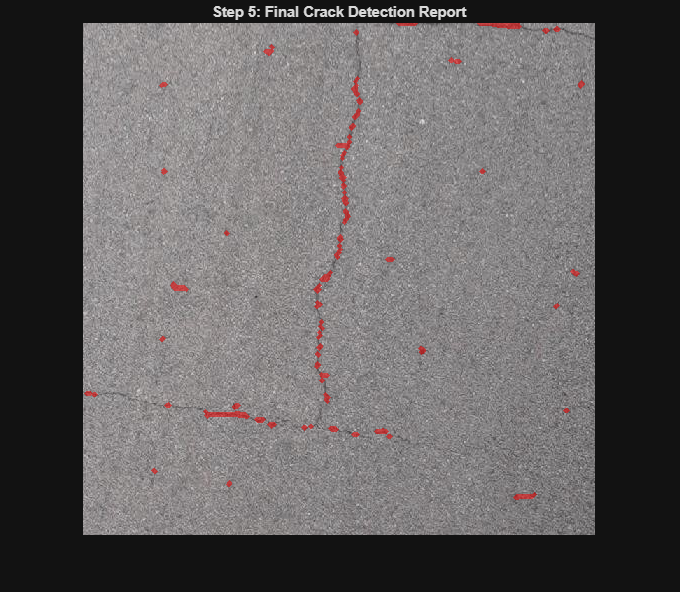


% --- Final Visualization (Revised) ---

figure;
imshow(img_color);
title('Step 5: Final Crack Detection Report');
hold on; 

% --- START OF FIX ---
% 1. Get the list of pixel locations for *all* blobs
all_blobs_pixels = cc.PixelIdxList;

% 2. Find the *indices* of the blobs we want to keep
%    (i.e., the ones that passed our area filter)
clean_blob_indices = find([stats.Area] > MIN_AREA_THRESHOLD);

% 3. Create a new, empty (all black) mask
BW_filtered_mask = false(size(BW_final));

% 4. Loop through only our "clean" indices and add them to the new mask
for i = 1:length(clean_blob_indices)
    idx = clean_blob_indices(i);
    BW_filtered_mask(all_blobs_pixels{idx}) = true;
end
% --- END OF FIX ---

% Create a red "image" 
red_overlay = cat(3, ones(size(BW_final)), ...
                     zeros(size(BW_final)), ...
                     zeros(size(BW_final)));

% Display the red overlay, but use our NEW filtered mask
h = imshow(red_overlay);
set(h, 'AlphaData', BW_filtered_mask * 0.5); % 50% transparency

hold off;